# Deep Learning

addpath("RandomImages/");

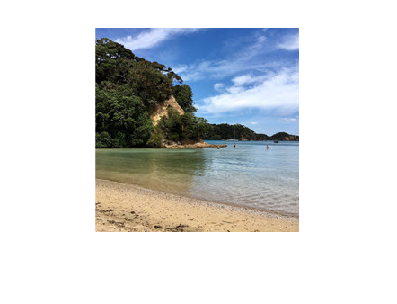

img1 = imread("file01.jpg");
imshow(img1);

## Using Neural Networks

Load a neural network:

net = imagePretrainedNetwork %load the neural network

net =   dlnetwork with properties:

         Layers: [68×1 nnet.cnn.layer.Layer]
    Connections: [75×2 table]
     Learnables: [52×3 table]
          State: [0×3 table]
     InputNames: {'data'}
    OutputNames: {'prob_flatten'}
    Initialized: 1

  View summary with summary.


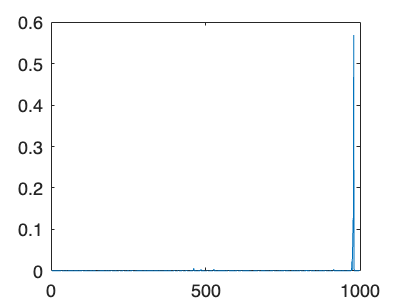

s1 = minibatchpredict(net,img1); % give the network an image
plot(s1); % plot the result, in this case we get a value 

[net,classes] = imagePretrainedNetwork; % load the network with its classes (categories)
c1 = scores2label(s1,classes) % transform the score of the picture given to the most probable category to get the reslt.

c1 = categorical
     seashore 


In this case the result is "seashore".

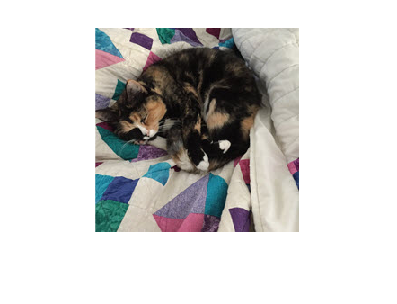

img2 = imread("file02.jpg");
imshow(img2);

s2 = minibatchpredict(net,img2);
c2 = scores2label(s2,classes)

c2 = categorical
     Gordon setter 


The result here is "Gordon Setter".

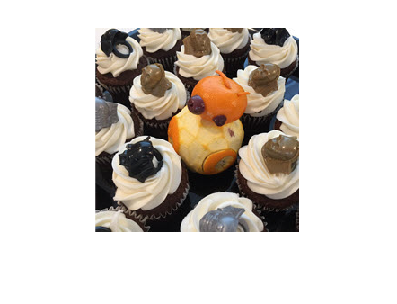

img3 = imread("file03.jpg");
imshow(img3);

s3 = minibatchpredict(net,img3);
c3 = scores2label(s3,classes)

c3 = categorical
     bakery 


The result is "bakery".

## Using Googlenet

[net,classes] = imagePretrainedNetwork("googlenet"); % load the network with its classes (categories)
s1 = minibatchpredict(net,img1); % give the network an image
c1 = scores2label(s1,classes) % transform the score of the picture given to the most probable category to get the reslt.

c1 = categorical
     seashore 


In this case the result is "seashore".

s2 = minibatchpredict(net,img2);
c2 = scores2label(s2,classes)

c2 = categorical
     Bernese mountain dog 


The result here is "Gordon Setter".

s3 = minibatchpredict(net,img3);
c3 = scores2label(s3,classes)

c3 = categorical
     bakery 


## Analyzing all images

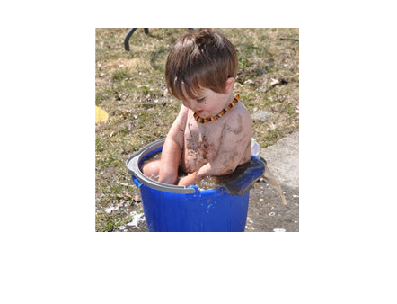

%ls("RandomImages/*.jpg")
imds = imageDatastore("RandomImages/*.jpg");
fname = imds.Files;
img = readimage(imds,7);
imshow(img);

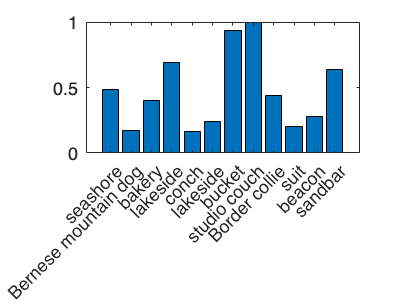

scores = minibatchpredict(net, imds);
preds = scores2label(scores,classes);
max(scores,[],2);
bar(max(scores,[],2));
xticklabels(preds);

## Adjust Input Images

The initial size of image 01 is:

img = imread("file01.jpg");
imshow(img)

sz = size(img)

sz =    227   227     3


Let us see the network characteristics:

summary(net);


   Initialized: true

   Number of learnables: 6.9M

   Inputs:
      1   'data'   224×224×3 images



Since the sizes do not match, we can rezise the image and see if the result chane:

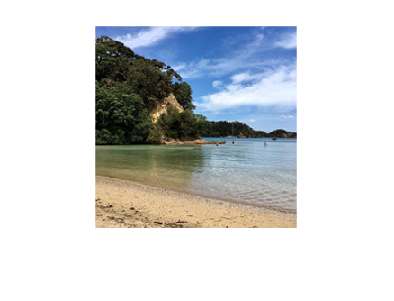

img = imresize(img,[224 224]);
imshow(img)

s = minibatchpredict(net,img);
c = scores2label(s,classes)

c = categorical
     seashore 


## Adjust for all Images

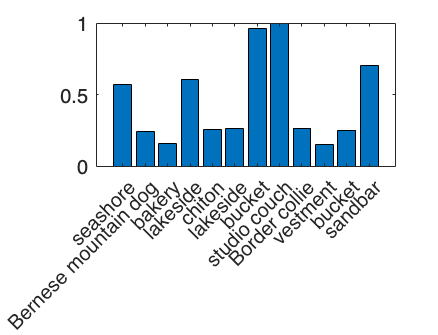

auds = augmentedImageDatastore([224 224], imds);
scores = minibatchpredict(net, auds);
preds = scores2label(scores,classes);
max(scores,[],2);
bar(max(scores,[],2));
xticklabels(preds);

We got some different results in this case.

## Adjust model for flowers

pathToImages = "flower_photos/";
%% Code to Download Images from internet
% mkdir(pathToImages)
% url = "http://download.tensorflow.org/example_images/flower_photos.tgz";
% filename = fullfile(pathToImages, "flower_dataset.tgz");
% websave(filename, url);
% untar(filename, pathToimages);


Create the datastore:

flowerds = imageDatastore(pathToImages,IncludeSubfolders=true,LabelSource="foldernames");
flowernames = flowerds.Labels;

Split into randomized testing and training:

rng default
[trainImgs, testImgs] = splitEachLabel(flowerds,0.8,"randomized");
% Or for Unbalanced Training Data
% [flwrTrain,flwrTest] = splitEachLabel(flwrds,500);

Resize Datastores:

resizeTrainImages = augmentedImageDatastore([224 224],trainImgs);
resizeTestImages = augmentedImageDatastore([224 224],testImgs);
classes = categories(flowerds.Labels);

## Create a Network by modifying GoogLeNet

net = imagePretrainedNetwork("googlenet",NumClasses=numel(classes));
%deepNetworkDesigner(net)

## Set option

options = trainingOptions("sgdm",Metrics="accuracy",Plots="training-progress");

## Training

    Iteration    Epoch    TimeElapsed    LearnRate    TrainingLoss    TrainingAccuracy
    _________    _____    ___________    _________    ____________    ________________
            1        1       00:00:07         0.01          3.6858              16.406
           50        3       00:03:17         0.01         0.22432              91.406
          100        5       00:06:25         0.01         0.10084              95.312
          150        7       00:09:29         0.01        0.093948              96.094
          200       10       00:12:35         0.01        0.032037              99.219
          250       12       00:15:39         0.01         0.01171              99.219
          300       14       00:18:44         0.01         0.00531                 100
          350       16       00:21:49         0.01         0.01716              99.219
          400       19       00:24:54         0.01      0.00081734                 100
          450       21       00:27:59      

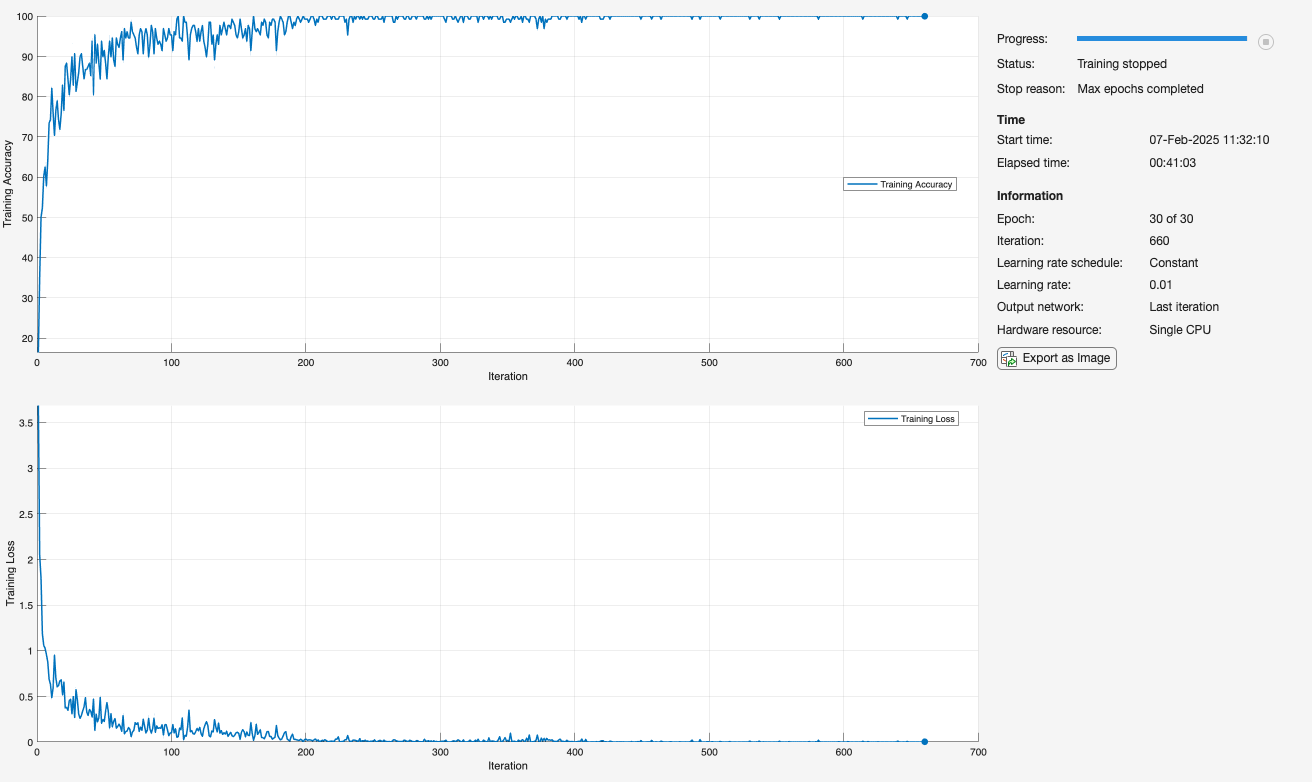

[flowernet,info] = trainnet(resizeTrainImages, net, "crossentropy",options);

## Evaluate Results

Calculate the accuracy:

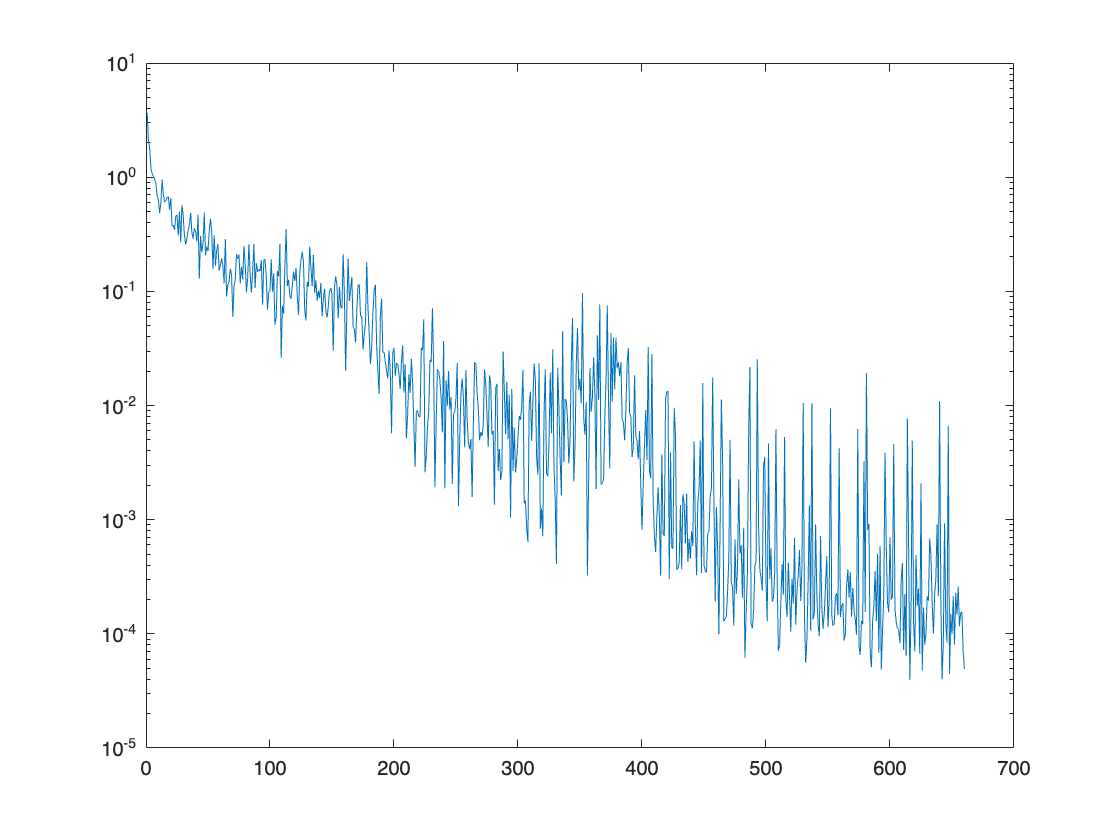

th = info.TrainingHistory;
%plot(th.Loss)
semilogy(th.Loss)

a = testnet(flowernet,resizeTestImages,"accuracy")

a = 93.7415

testscores = minibatchpredict(flowernet,resizeTestImages);
testpreds = scores2label(testscores,classes)

testpreds = 735×1 categorical array
     daisy 
     daisy 
     daisy 
     daisy 
     daisy 
     daisy 
     daisy 
     daisy 
     daisy 
     daisy 
     sunflowers 
     daisy 
     daisy 
     daisy 
     daisy 
     daisy 
     daisy 
     daisy 
     daisy 
     daisy 
     daisy 
     daisy 
     daisy 
     daisy 
     daisy 
     daisy 
     daisy 
     daisy 
     daisy 
     dandelion 


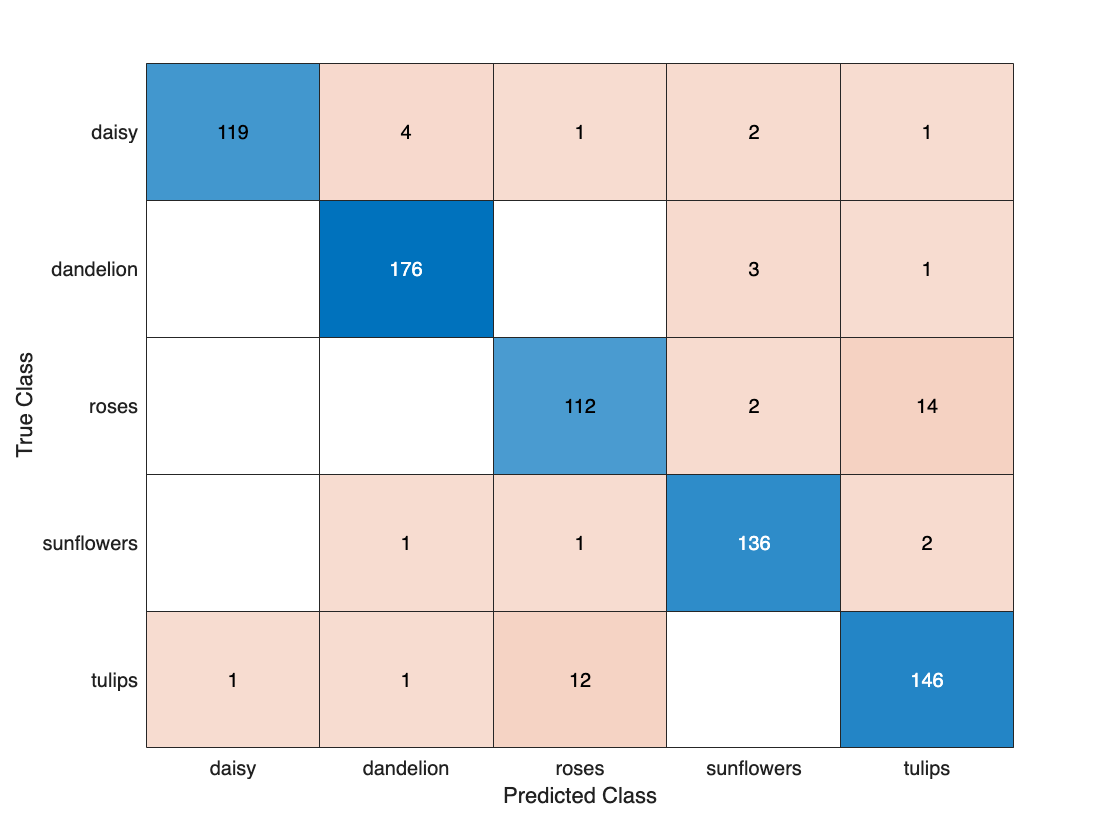

truetest = testImgs.Labels;
confusionchart(truetest,testpreds);

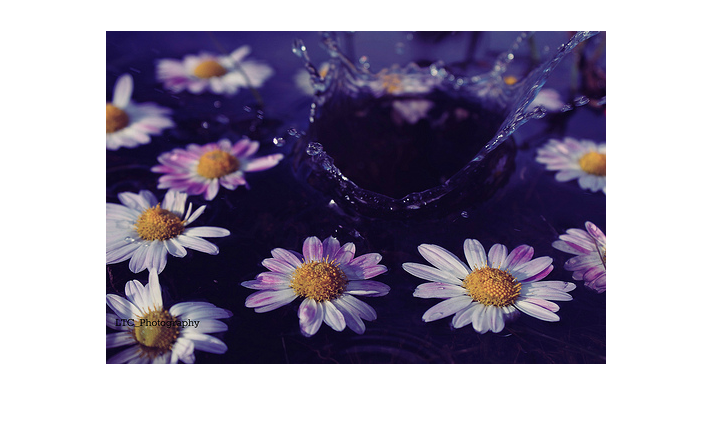

AI predicted daisy, but it should be dandelion


idx = find(testpreds~=truetest);
idmax = size(idx);
idmaxval = idmax(1,1);
iderror = 3;
if ~isempty(idx)
    imshow(readimage(testImgs,iderror));
    realvalue=testpreds(idx(iderror));
    testvalue=truetest(idx(iderror));
    fprintf("AI predicted %s, but it should be %s\n", testvalue, realvalue);
end